# EE115 Lab 2

# Buddy Ugwumba

To detect the envelope of $u\left(t\right)=A\;\left(a_{\mathrm{mod}} m_n \left(t\right)+1\right)\mathrm{cos}\left(2\pi f_c t\right)$, we need a diode, a capacitor and a resistor. Assume that the diode has a resistance $R_s$ when the voltage across it is positive (however small) and a resistance $R_o >>R_s$, when the voltage across it is negative. The resistor has the resistance $R_l$ which satisfies $R_o >>R_l >>R_s$, The capacitor has the capacitance $C$. Answer the following questions and/or perform the following tasks:										

1)  If $f_c =10\textrm{MHz}$, what is a proper range of $R_s C$? 

Below is the inequality the represents the relationship between the frequency of the carrier signal and the $R_s C$ (Resistance of the diode with the capacitor):

$R_s C<<\frac{1}{f_c }$ = $R_s C<<\frac{1}{10\mathrm{MHz}}$	

Thus, the proper range is: $R_s C<<100\mathrm{ns}$. Meaning $R_s C$ needs to be much smaller than $100ns$ but larger than 0. Effectively that range would be from 0 to 10ps

2)  If $m\left(t\right)$ has a bandwidth $B$ equal to 10kHz, what is a proper range of $R_l C$?

The relationship between the $R_l C$ and the bandwidth (the amount of information transferred per second) of the signal is as follows:


$$\frac{1}{f_c }<<R_l C<<\frac{1}{B}$$


 Thus, the proper range is: ${10\mu s<<\;R}_l C\;<<100\mathrm{Ms}$. Meaning $R_l C$ needs to be much smaller than 100Ms but larger than 0. Effective that range would be from 0 to 10hs					

3)  If $R_s ={10}^{-3} \;\Omega$ and $R_l =5\Omega$, how do youo choose $C$ to meet the above conditions?

The relationship between time $\tau$ and the RC circuit is:

$\tau =R_{s/l} C=\frac{1}{2\pi f_c }$ -> $C=\frac{1}{2\pi f_c R_{s/l} }$

The capacitor should be $3\ldotp 1831\mathrm{nF}<<\;C<<3\mu F$

4)  Sketch the equivalent circuit (of the envelope detector) when the capacitor is in charging mode, and the equivalent circuit when the capacitor is in discharging mode.

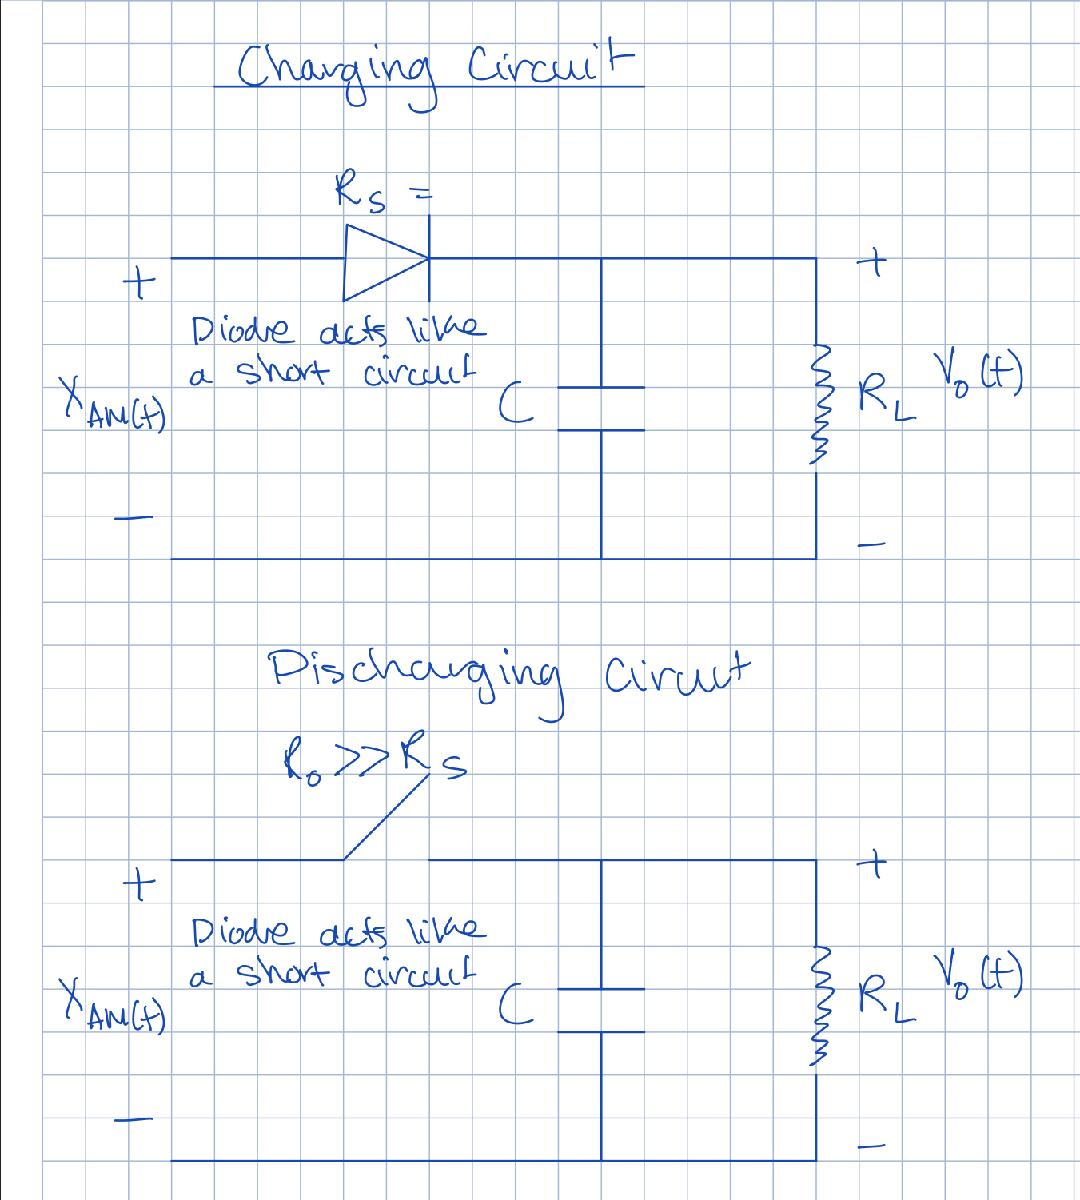 						

5)  Let the input voltage be $v\left(t\right)=\delta \left(t\right)$. Determine the corresponding output voltage (impulse response) $h_c \left(t\right)$ of the circuit in the charging mode. How does $h_c \left(t\right)$ relate to $R_s C$? If $v_i \left(t\right)=u\left(t\right)$ (step function), what would be the output voltage (step response) of the circuit? 

Every linear time-invariant signal can be completely characterized by the impulse repsonse. The impulse response can be found by taking the ratio of the output voltage to the input voltage. First step is convert the relationship between parallel components (capacitor and resistor) to the Laplace domain 


$$\frac{V_0 \left(s\right)}{V_i \left(s\right)}=H\left(s\right)=\frac{\frac{1}{\frac{1}{R}+\mathrm{sC}}}{R_s +\frac{1}{\frac{1}{R}+\mathrm{sC}}}=\frac{1}{R_s \left(\frac{1}{R}+\mathrm{sC}\right)+1}=\frac{1}{1+\frac{R_s }{R}+R_s C}$$


We then assum that the ration between $\frac{R_s }{R}<<1$ thus,


$$V_0 \left(s\right)=\frac{1}{1+{\mathrm{sR}}_s C}V_i \left(s\right)\;$$



$$V_0 \left(t\right)=e^{-\frac{1}{R_s C}t}$$


The relation between $h_c \left(t\right)$ and $R_s C$ is that the larger the impediance from the RC circuit the lower the output voltage. Specifically, the larger the value of $R_s C$ the faster the output voltage decays.

When the input voltage is the step response, the output voltage is:


$$V_0 \left(s\right)=\frac{1}{1+{\mathrm{sR}}_s C}*\frac{1}{s}=\frac{1}{S}-\frac{R}{1+{\mathrm{sR}}_s C}$$


Thus the output voltage would be: $V_o \left(t\right)=u\left(t\right)-e^{-\frac{1}{R_s C}t} u\left(t\right)$

6)  If the output voltage is initially at $h_d \left(0\right)=V$, determine the free response of the output voltage $h_d \left(t\right)$ in the discharging mode. How does $h_d \left(t\right)$ relate to $R_l C$?

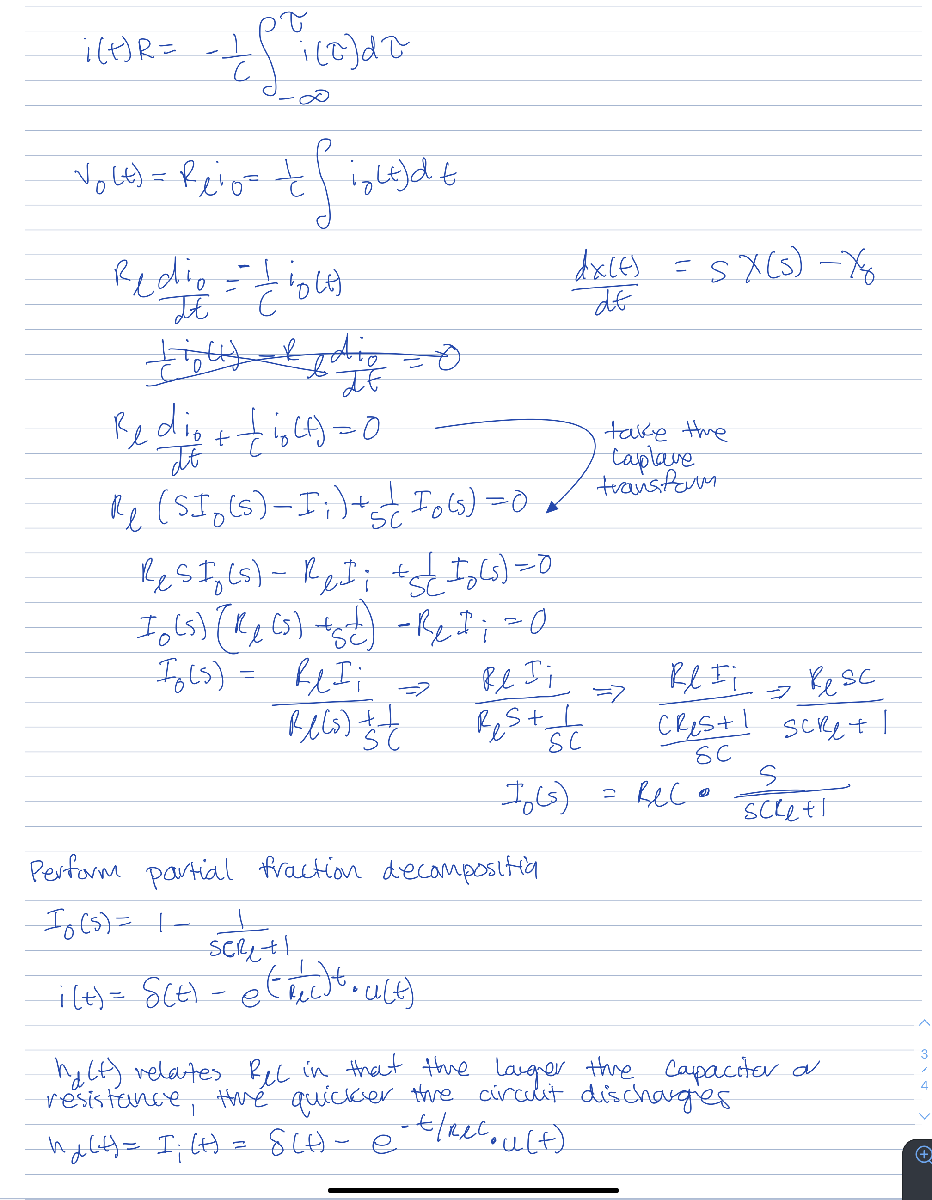

7) Assume $A=1,a_{\mathrm{mod}} =0\ldotp 5,$ and $m\left(t\right)=\mathrm{sinc}\left(20\;x\;{10}^3 t\right)=\frac{\mathrm{sin}\left(\pi 20{\mathrm{x10}}^3 t\right)}{\pi 20{\mathrm{x10}}^3 t}$. Plot the envelope of $u\left(t\right)$ for $-0\ldotp 5\;z\;{10}^{-3} <t<0\ldotp 5\;x\;{10}^{-3}$

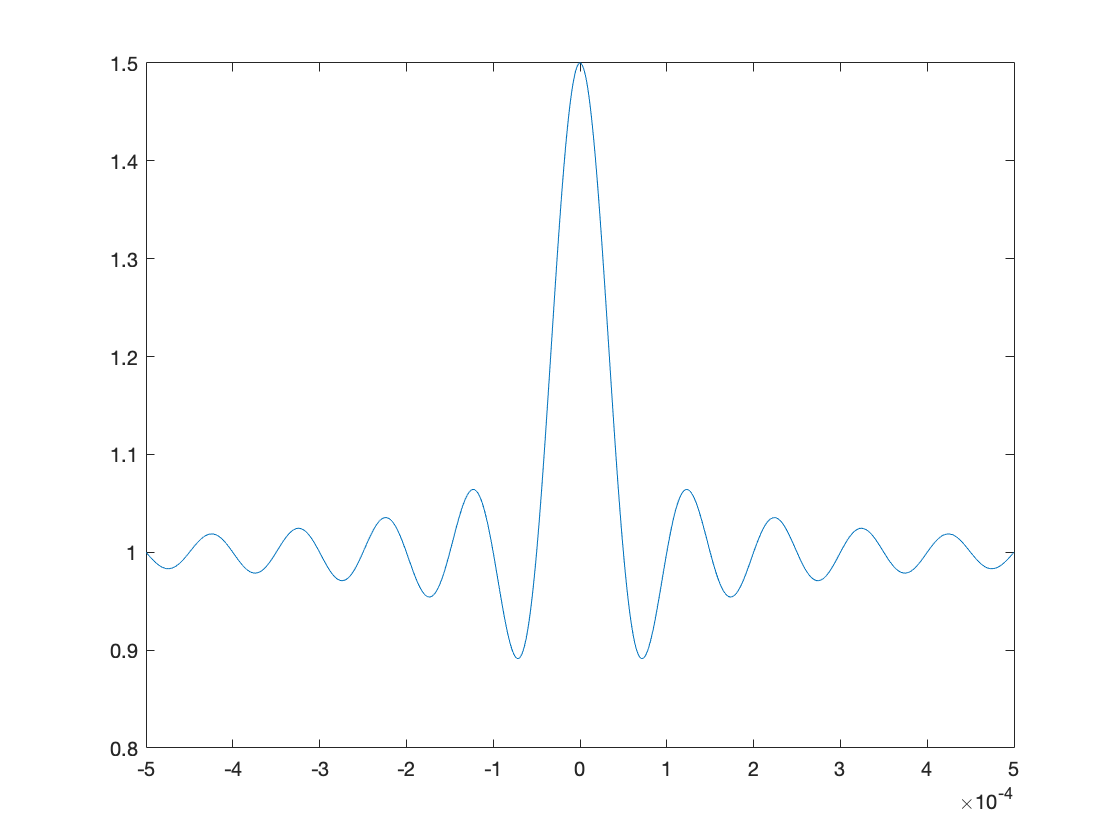

t = -0.5*10^-3:0.0000001:0.5*10^-3;
y_t = 1+0.5*sinc(20*10^3*t);
figure
plot(t,y_t)

8) Now let $f_c =80\;x\;{10}^3$. Plot  $u\left(t\right)$ for $-0\ldotp 5\;x{10}^{-3} <t<0\ldotp 5\;x\;{10}^{-3}$ for and compaire it with its envelope. 

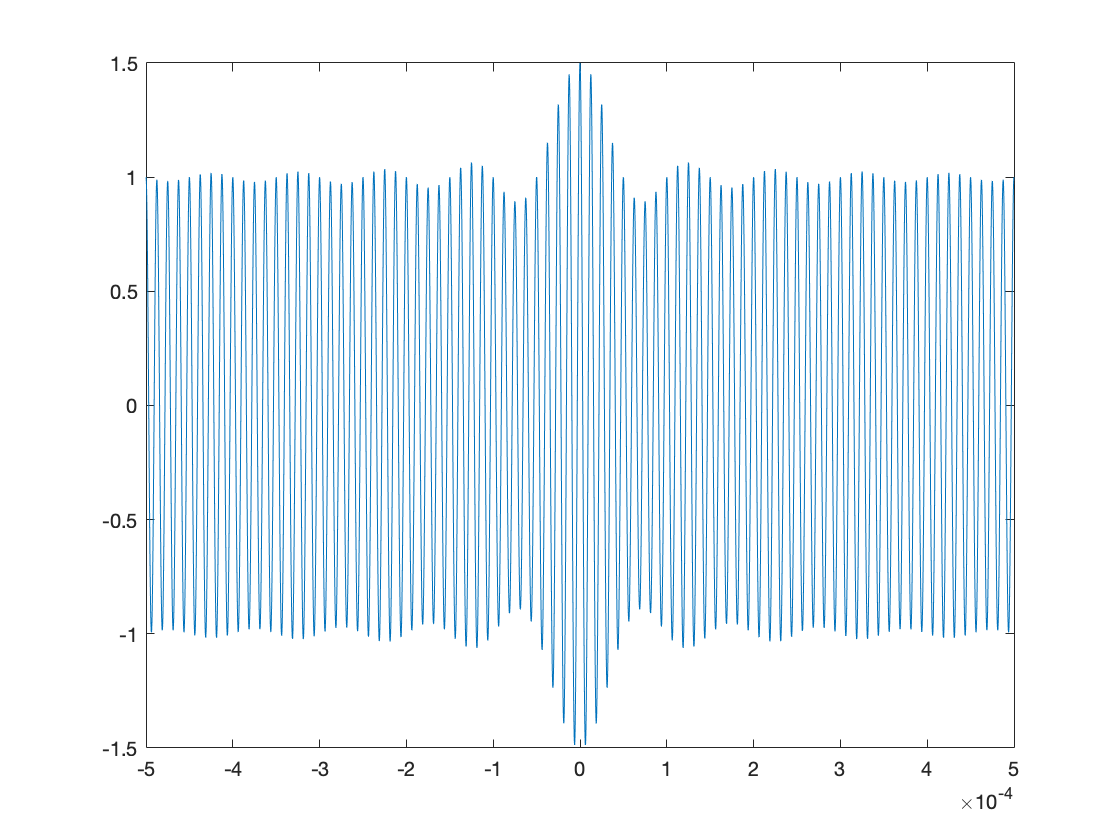

u_t = (1+0.5*sinc(20*10^3*t)).*cos(2*pi*80*10^3*t);
figure
plot(t,u_t)